% Wednesday, 12 May 2021 09:18:57
% 10600nm 1550nm 532nm
% PERCENTAGE
% BASELINE[LWIR/SWIR/VIS]: 1.04116906881332 0.945331764221191 0.896040351390839
% BASELINE_REFERENCE[LWIR/SWIR/VIS]: 1 1 1
% SECONDS LWIR_Meas SWIR_Meas VIS_Meas LWIR_Pick SWIR_Pick VIS_Pick LWIR_Disp SWIR_Disp VIS_Disp

fog01_startidx = 3938

fog01_startidx = 3938

fog01_endidx = 5435

fog01_endidx = 5435


fog_data = load("sriram/src/files/fog_properties_20210511.mat")

fog_data = struct with fields:
             time: [20737×1 double]
     transmission: [20737×3 double]
           MOR532: [20737×4 double]
       extinction: [20737×3 double]
              LWC: [20737×1 double]
               Nd: [20737×3 double]
    numberDisNorm: [20737×60 double]
        diameters: [0.1082 0.1261 0.1466 0.1710 0.1994 0.2323 0.2712 0.3161 0.3684 0.4297 0.5010 0.5843 0.6815 0.7947 0.9263 1.0798 1.2588 1.4677 1.7115 1.9951 2.3261 2.7125 3.1627 3.6872 4.2988 5.0122 5.8438 6.8130 7.9431 9.2612 10.7977 12.5894 … ]
          datenum: 738287
             date: '11-May-2021'


fog_data.time = fog_data.time(fog01_startidx:fog01_endidx) - fog_data.time(fog01_startidx);
fog_data.LWC = fog_data.LWC(fog01_startidx:fog01_endidx);

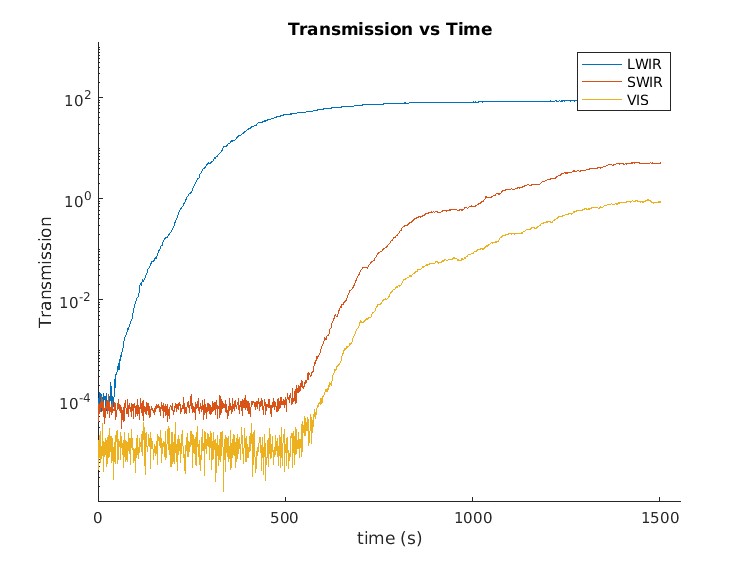

trans_lwir = fog_data.transmission(:, 1);
trans_swir = fog_data.transmission(:, 2);
trans_vis = fog_data.transmission(:, 3);

trans_lwir = trans_lwir(fog01_startidx:fog01_endidx);
trans_swir = trans_swir(fog01_startidx:fog01_endidx);
trans_vis = trans_vis(fog01_startidx:fog01_endidx);

figure;
hold on;
plot(fog_data.time, trans_lwir)
plot(fog_data.time, trans_swir)
plot(fog_data.time, trans_vis)
set(gca, 'YScale', 'log')

xlabel('time (s)')
ylabel('Transmission')
title("Transmission vs Time")
legend("LWIR", "SWIR", "VIS")
hold off;

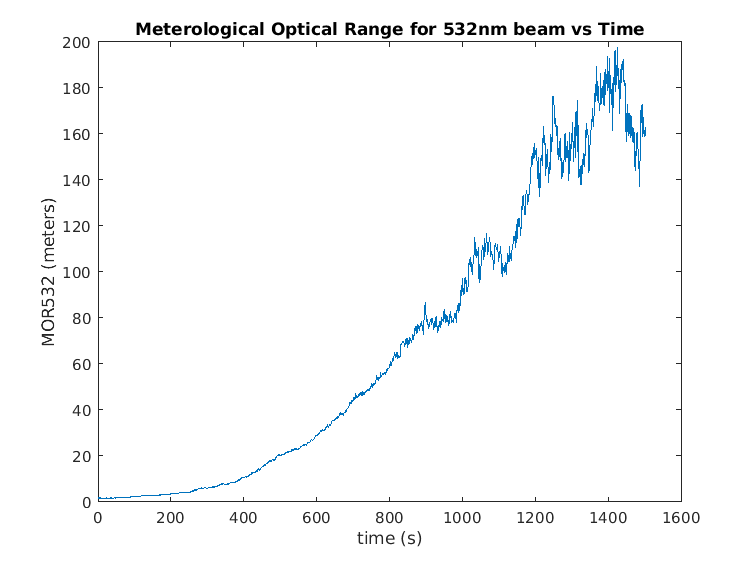

mor_vis = fog_data.MOR532(:, 1);
mor_vis = mor_vis(fog01_startidx:fog01_endidx);
plot(fog_data.time, mor_vis)

xlabel('time (s)')
ylabel('MOR532 (meters)')
title("Meterological Optical Range for 532nm beam vs Time")

plot(fog_data.time, fog_data.extinction)

Error using plot
Vectors must be the same length.

xlabel('time (s)')
ylabel('Extinction (dimensionless)')
title("Extinction Coefficients vs Time")
legend("LWIR", "SWIR", "VIS")

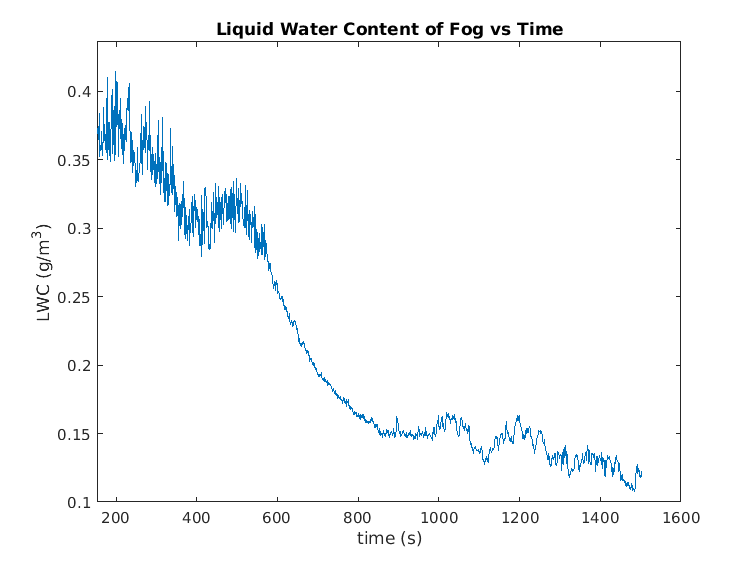

plot(fog_data.time, fog_data.LWC)
xlabel('time (s)')
ylabel('LWC (g/m^3)')
title("Liquid Water Content of Fog vs Time")

plot(fog_data.time, fog_data.Nd)

Error using plot
Vectors must be the same length.

xlabel('time (s)')
ylabel('Nd (par/m^3)')
title("Number of Particles Suspended vs Time")
legend("LWIR", "SWIR", "VIS")